rowNames = {'First Approach', 'Second Approach', 'Third Approach'};
columnNames = {'N = 10000' 'N = 20000' 'N = 30000' 'N = 40000' 'N = 50000' 'N = 60000' 'N = 70000' 'N = 80000' 'N = 90000' 'N = 100000'};

T = table([29639;116791;264081;470469;733966;1057253;1448531;1876498;2402131;2935325],...
          [3057;5378;7045;9906;12521;15651;17873;20771;23716;26762],...
          [42;74;220;307;367;448;516;653;779;834],...
           'RowNames',columnNames,...
           'VariableNames', rowNames);

uitable('Data',T{:,:},'ColumnName',T.Properties.VariableNames,'RowName',T.Properties.RowNames, 'Units', 'Normalized', 'Position', [0, 0, 1, 1], 'ColumnWidth', {120});
saveas(gcf, 'table.pdf');

figure;

for i = 1:size(T, 2)
    subplot(1, size(T, 2), i);
    scatter(1:size(T, 1), T{:, i});
    hold on;
    
    % Fit linear regression
    linear_mdl = fitlm((1:size(T, 1))', T{:, i});
    linear_coeffs(i, :) = linear_mdl.Coefficients.Estimate';
    x_values = 1:size(T, 1);
    y_values_linear = linear_mdl.Coefficients.Estimate(1) + x_values * linear_mdl.Coefficients.Estimate(2);
    plot(x_values, y_values_linear, 'b', 'LineWidth', 2);
    
    % Compute R^2 for linear regression
    linear_r_squared = linear_mdl.Rsquared.Ordinary;

    % Fit quadratic regression using 'fit' function
    quad_fun = fittype('a*x^2 + b*x + c', 'independent', 'x', 'dependent', 'y');
    quad_mdl = fit((1:size(T, 1))', T{:, i}, quad_fun);
    
    % Generate values for plotting quadratic regression
    x_values_quad = linspace(1, size(T, 1), 100);
    y_values_quad = feval(quad_mdl, x_values_quad);
    %plot(x_values_quad, y_values_quad, 'r', 'LineWidth', 2);
    
    % Compute R^2 for quadratic regression
    quad_residuals = T{:, i} - feval(quad_mdl, (1:size(T, 1))');
    quad_ssr = sum(quad_residuals.^2);
    quad_total_sst = sum((T{:, i} - mean(T{:, i})).^2);
    quad_r_squared = 1 - quad_ssr / quad_total_sst;

    title(rowNames{i});
    xlabel('Array size (×1e5)');
    ylabel('Time in μs');
    ylim([0, max(T{:, i})]); % Set y-axis limit according to the maximum value in each column
    hold off;

    % Display R^2 values
    disp(['Linear Regression R^2 for ', rowNames{i}, ':']);
    disp(linear_r_squared);
    disp(['Quadratic Regression R^2 for ', rowNames{i}, ':']);
    disp(quad_r_squared);
end

Linear Regression R^2 for First Approach:


    0.9499



Quadratic Regression R^2 for First Approach:


    0.9999



Linear Regression R^2 for Second Approach:


    0.9968



Quadratic Regression R^2 for Second Approach:


    0.9991



Linear Regression R^2 for Third Approach:


    0.9904



Quadratic Regression R^2 for Third Approach:


    0.9918



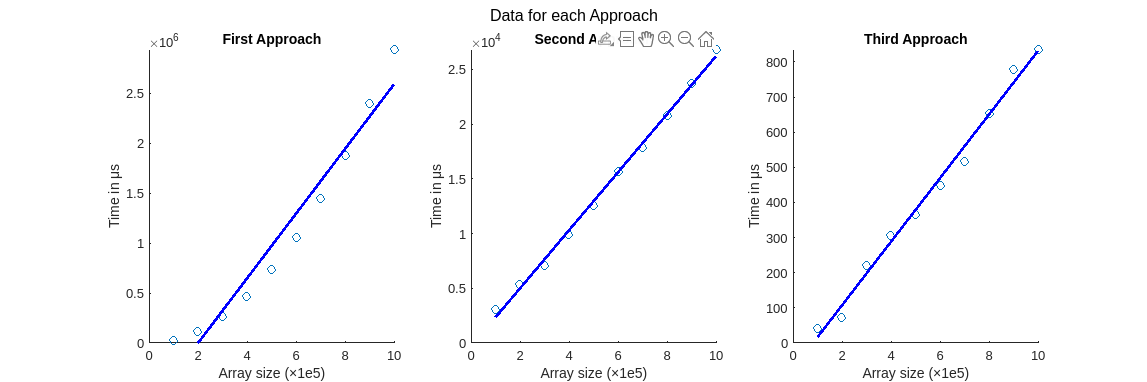

% Adjust subplot layout
sgtitle('Data for each Approach');

% Adjust figure size
set(gcf, 'Position', [100, 100, 1200, 400]);

% Save the figure as a JPG
saveas(gcf, 'column_plots.jpg');